%% ================================================================
% SECTION 5
% MATLAB-BASED RIS DISTANCE, SPACING AND LINK ANALYSIS
% ================================================================

clear;
clc;
close all;

%% ================================================================
% 1. SYSTEM PARAMETERS
% ================================================================

c = 3e8;                    % Speed of light [m/s]
f = 2.45e9;                 % Operating frequency [Hz]
lambda = c/f;               % Wavelength [m]

fprintf('====================================================\n');

fprintf(' RIS SYSTEM-LEVEL DISTANCE AND SPACING STUDY\n');

 RIS SYSTEM-LEVEL DISTANCE AND SPACING STUDY


fprintf('====================================================\n');


fprintf('Operating frequency = %.2f GHz\n',f/1e9);

Operating frequency = 2.45 GHz


fprintf('Wavelength          = %.2f mm\n',lambda*1000);

Wavelength          = 122.45 mm




%% ================================================================
% 2. RIS UNIT-CELL PARAMETERS
% ================================================================

% Unit-cell periodicity
% Your present HFSS design uses approximately 40 mm periodicity.

cell_spacing = 61e-3;       % 40 mm

fprintf('\nUnit-cell spacing = %.1f mm\n', ...
        cell_spacing*1000);


Unit-cell spacing = 61.0 mm




%% ================================================================
% 3. REAL-WORLD RIS SPACING STUDY
% ================================================================

% Candidate element spacings
%
% 20 mm  = 0.16 lambda
% 30 mm  = 0.25 lambda
% 40 mm  = 0.33 lambda
% 50 mm  = 0.41 lambda
%
% These values are used to study the effect of physical spacing.

spacing = [60]*1e-3;

spacing_lambda = spacing/lambda;

fprintf('\nRIS element spacing study:\n');


RIS element spacing study:



for n = 1:length(spacing)

    fprintf('Spacing = %2.0f mm = %.2f lambda\n', ...
        spacing(n)*1000, spacing_lambda(n));

end

Spacing = 60 mm = 0.49 lambda




%% ================================================================
% 4. ARRAY SIZE
% ================================================================

array_sizes = [2 4 8 16];

fprintf('\nArray configurations:\n');


Array configurations:



for n = 1:length(array_sizes)

    N = array_sizes(n)^2;

    aperture = array_sizes(n)*cell_spacing;

    fprintf('%2dx%2d array: %3d elements, aperture = %.0f mm\n', ...
        array_sizes(n), ...
        array_sizes(n), ...
        N, ...
        aperture*1000);

end

 2x 2 array:   4 elements, aperture = 122 mm
 4x 4 array:  16 elements, aperture = 244 mm
 8x 8 array:  64 elements, aperture = 488 mm
16x16 array: 256 elements, aperture = 976 mm


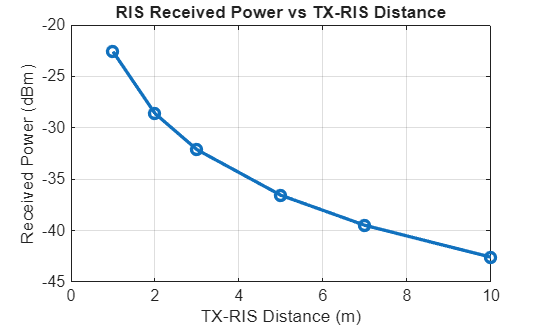



%% ================================================================
% 5. TX-RIS AND RIS-RX DISTANCES
% ================================================================

d_tx_ris = [1 2 3 5 7 10];

d_ris_rx = [1 2 3 5 7 10];


%% ================================================================
% 6. TRANSMITTER / RECEIVER PARAMETERS
% ================================================================

Pt_dBm = 20;                % TX power = 100 mW
Pt = 10^((Pt_dBm-30)/10);   % Convert dBm to watts

Gt_dBi = 8;                 % TX antenna gain
Gr_dBi = 8;                 % RX antenna gain

Gt = 10^(Gt_dBi/10);
Gr = 10^(Gr_dBi/10);


%% ================================================================
% 7. RIS EFFICIENCY
% ================================================================

% Represents losses caused by:
% diode,
% copper,
% substrate,
% bias network,
% imperfect phase alignment.

eta_RIS = 0.60;


%% ================================================================
% 8. RIS DISTANCE STUDY
% ================================================================

Nx = 4;
Ny = 4;

N = Nx*Ny;

Pr_RIS = zeros(length(d_tx_ris), ...
               length(d_ris_rx));


for i = 1:length(d_tx_ris)

    for j = 1:length(d_ris_rx)

        d1 = d_tx_ris(i);
        d2 = d_ris_rx(j);

        % TX -> RIS propagation
        FSPL1 = (lambda/(4*pi*d1))^2;

        % RIS -> RX propagation
        FSPL2 = (lambda/(4*pi*d2))^2;

        % Coherent RIS array contribution
        RIS_gain = N^2;

        % Simplified RIS received power model
        Pr_RIS(i,j) = Pt * Gt * Gr * ...
                      FSPL1 * FSPL2 * ...
                      RIS_gain * eta_RIS;

    end

end


%% ================================================================
% 9. CONVERT RIS POWER TO dBm
% ================================================================

Pr_RIS_dBm = 10*log10(Pr_RIS/1e-3);


%% ================================================================
% 10. PLOT TX-RIS DISTANCE
% ================================================================

figure;

plot(d_tx_ris, ...
     Pr_RIS_dBm(:,1), ...
     '-o', ...
     'LineWidth',2);

grid on;

xlabel('TX-RIS Distance (m)');
ylabel('Received Power (dBm)');

title('RIS Received Power vs TX-RIS Distance');

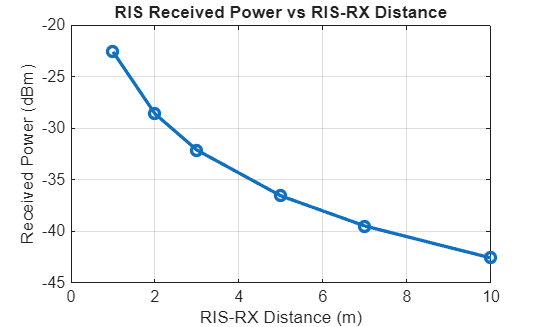



%% ================================================================
% 11. PLOT RIS-RX DISTANCE
% ================================================================

figure;

plot(d_ris_rx, ...
     Pr_RIS_dBm(1,:), ...
     '-o', ...
     'LineWidth',2);

grid on;

xlabel('RIS-RX Distance (m)');
ylabel('Received Power (dBm)');

title('RIS Received Power vs RIS-RX Distance');

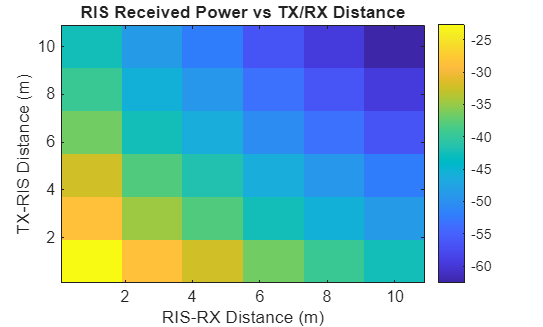



%% ================================================================
% 12. 2-D DISTANCE MAP
% ================================================================

figure;

imagesc(d_ris_rx, ...
        d_tx_ris, ...
        Pr_RIS_dBm);

colorbar;

xlabel('RIS-RX Distance (m)');
ylabel('TX-RIS Distance (m)');

title('RIS Received Power vs TX/RX Distance');

set(gca,'YDir','normal');

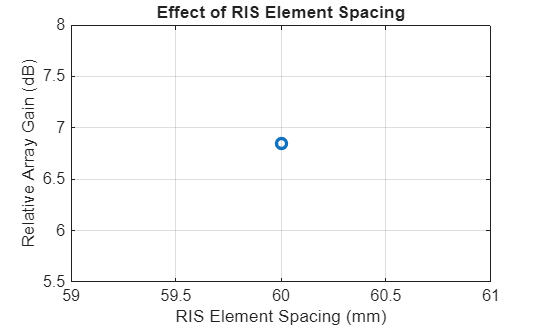



%% ================================================================
% 13. RIS ELEMENT SPACING STUDY
% ================================================================

% Use 4x4 RIS for comparison.

N_elements = 16;

spacing_gain = zeros(size(spacing));

for n = 1:length(spacing)

    d = spacing(n);

    % Approximate aperture-dependent gain
    aperture_factor = ...
        (N_elements*d^2)/(lambda^2);

    spacing_gain(n) = ...
        10*log10(1 + aperture_factor);

end


figure;

plot(spacing*1000, ...
     spacing_gain, ...
     '-o', ...
     'LineWidth',2);

grid on;

xlabel('RIS Element Spacing (mm)');
ylabel('Relative Array Gain (dB)');

title('Effect of RIS Element Spacing');



%% ================================================================
% 14. REAL-WORLD SPACING CONSTRAINT
% ================================================================

% Practical minimum spacing constraint.
%
% This is not a universal manufacturing limit.
% It is a design constraint used for this study.

min_spacing = 10e-3;

valid_spacing = spacing >= min_spacing;

fprintf('\nReal-world spacing check:\n');


Real-world spacing check:



for n = 1:length(spacing)

    if valid_spacing(n)

        fprintf('%.0f mm : ACCEPTABLE\n', ...
            spacing(n)*1000);

    else

        fprintf('%.0f mm : TOO SMALL\n', ...
            spacing(n)*1000);

    end

end

60 mm : ACCEPTABLE


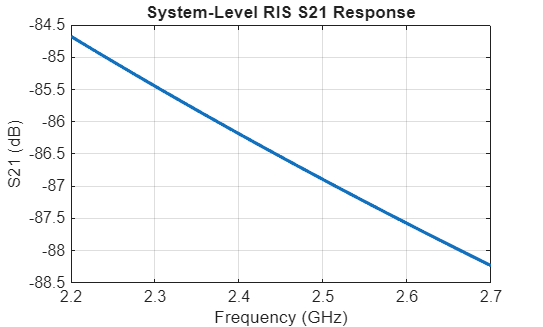



%% ================================================================
% 15. S21 SYSTEM-LEVEL MODEL
% ================================================================

% Frequency sweep

freq = linspace(2.2e9,2.7e9,501);

S21_dB = zeros(size(freq));

% Reference distance
d1 = 5;
d2 = 5;

% 4x4 RIS

N = 16;

for k = 1:length(freq)

    lambda_f = c/freq(k);

    % TX -> RIS
    path1 = lambda_f/(4*pi*d1);

    % RIS -> RX
    path2 = lambda_f/(4*pi*d2);

    % Simplified coherent RIS transmission factor
    H_RIS = path1 * path2 * N * sqrt(eta_RIS);

    % Convert to dB
    S21_dB(k) = 20*log10(abs(H_RIS));

end


%% ================================================================
% 16. S21 PLOT
% ================================================================

figure;

plot(freq/1e9, ...
     S21_dB, ...
     'LineWidth',2);

grid on;

xlabel('Frequency (GHz)');
ylabel('S21 (dB)');

title('System-Level RIS S21 Response');

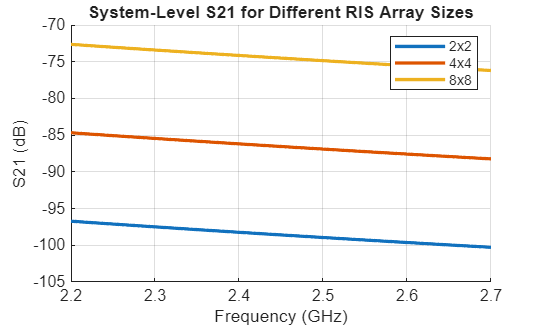



%% ================================================================
% 17. S21 COMPARISON FOR DIFFERENT ARRAY SIZES
% ================================================================

array_compare = [2 4 8];

figure;
hold on;

for a = 1:length(array_compare)

    N = array_compare(a)^2;

    S21_temp = zeros(size(freq));

    for k = 1:length(freq)

        lambda_f = c/freq(k);

        path1 = lambda_f/(4*pi*d1);
        path2 = lambda_f/(4*pi*d2);

        H = path1 * path2 * ...
            N * sqrt(eta_RIS);

        S21_temp(k) = ...
            20*log10(abs(H));

    end

    plot(freq/1e9, ...
         S21_temp, ...
         'LineWidth',2);

end

grid on;

xlabel('Frequency (GHz)');
ylabel('S21 (dB)');

title('System-Level S21 for Different RIS Array Sizes');

legend('2x2','4x4','8x8');



%% ================================================================
% 18. REAL-WORLD DEPLOYMENT LIMITATIONS
% ================================================================

fprintf('\n====================================================\n');

fprintf(' REAL-WORLD RIS CONSIDERATIONS\n');

 REAL-WORLD RIS CONSIDERATIONS


fprintf('====================================================\n');


fprintf('1. PCB fabrication tolerance\n');

1. PCB fabrication tolerance


fprintf('2. PIN diode parasitics\n');

2. PIN diode parasitics


fprintf('3. RF choke parasitics and self-resonance\n');

3. RF choke parasitics and self-resonance


fprintf('4. Bias-line electromagnetic coupling\n');

4. Bias-line electromagnetic coupling


fprintf('5. FR4 dielectric losses\n');

5. FR4 dielectric losses


fprintf('6. Connector and soldering losses\n');

6. Connector and soldering losses


fprintf('7. Finite RIS aperture\n');

7. Finite RIS aperture


fprintf('8. Mutual coupling between adjacent elements\n');

8. Mutual coupling between adjacent elements


fprintf('9. Phase quantization error\n');

9. Phase quantization error


fprintf('10. TX/RX alignment and antenna orientation\n');

10. TX/RX alignment and antenna orientation


fprintf('11. Near-field/far-field operating region\n');

11. Near-field/far-field operating region


fprintf('12. Physical mounting and mechanical spacing\n');

12. Physical mounting and mechanical spacing




%% ================================================================
% 19. SUMMARY
% ================================================================

fprintf('\n====================================================\n');

fprintf(' SECTION 5 COMPLETE\n');

 SECTION 5 COMPLETE


fprintf('====================================================\n');


fprintf('Operating frequency : %.2f GHz\n',f/1e9);

Operating frequency : 2.45 GHz


fprintf('Unit-cell spacing   : %.1f mm\n',cell_spacing*1000);

Unit-cell spacing   : 61.0 mm


fprintf('RIS array           : %dx%d\n',Nx,Ny);

RIS array           : 4x4


fprintf('TX-RIS distances    : 1-10 m\n');

TX-RIS distances    : 1-10 m


fprintf('RIS-RX distances    : 1-10 m\n');

RIS-RX distances    : 1-10 m


fprintf('RIS efficiency      : %.0f %%\n',eta_RIS*100);

RIS efficiency      : 60 %



fprintf('\nNext stage:\n');


Next stage:


fprintf('HFSS validation with bias lines and RF chokes.\n');

HFSS validation with bias lines and RF chokes.
